# a) External Controls, Changes control status of pump STEP BY STEP.

## This example contains: 

- Load network. 

- Delete Controls. 

- Hydraulic analysis STEP-BY-STEP. 

- CONTROLS: Add new controls in live. 

- Unload library.

## Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Load network.

d = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.2 - Last Update: 07/08/2022}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


## Delete Controls.

d.deleteControls();
tankID = '2';
pumpID = '9';

tankIndex = d.getNodeIndex(tankID);
pumpIndex = d.getLinkIndex(pumpID);
tankElevation = d.getNodeElevations(tankIndex);

## Hydraulic analysis STEP-BY-STEP.

d.openHydraulicAnalysis;
d.initializeHydraulicAnalysis(0);

tstep = 1; i = 1;
T = []; P = []; F = []; S= [];

## CONTROLS.

Below = 110;
Above = 140;
tankHead = [];
while (tstep>0)
    
    H = d.getNodeHydaulicHead;
    tankHead(i) = H(tankIndex)-tankElevation;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Add new controls in live.
    % LINK 9 OPEN IF NODE 2 BELOW 110
    if tankHead(i) < Below
        d.setLinkStatus(pumpIndex, 1);
    end
    % LINK 9 CLOSED IF NODE 2 ABOVE 140
    if tankHead(i) > Above
        d.setLinkStatus(pumpIndex, 0);
    end
    i = i+1;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    t = d.runHydraulicAnalysis;
    
    S = [S; d.getLinkStatus(pumpIndex)];
    F = [F; d.getLinkFlows];
    P = [P; d.getNodePressure(1)];
    T = [T; t];
    
    tstep = d.nextHydraulicAnalysisStep;
end
d.closeHydraulicAnalysis;

## Unload library.

d.unload;

EPANET Class is unloaded


## Create figures

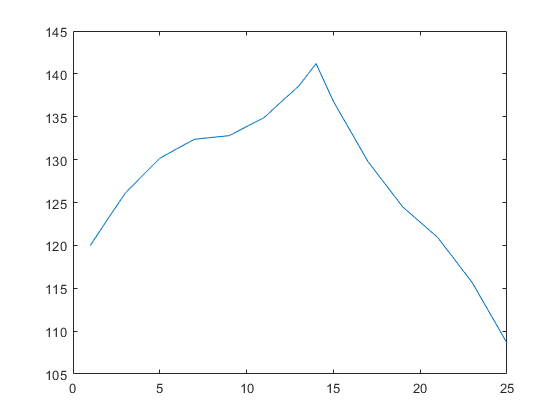

figure;
plot(tankHead)

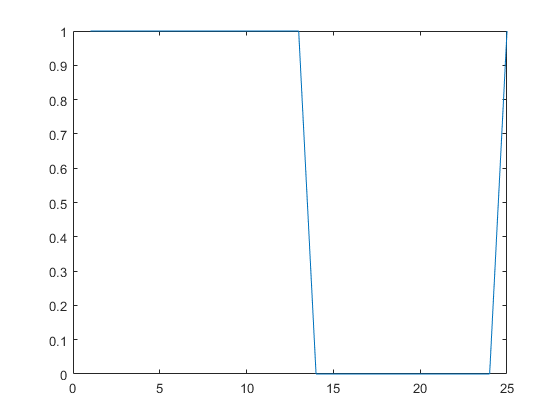

figure;
plot(S)